clc; clearvars;

tempo_path = "C:\NERTO_drive\TEMPO_data";
tropomi_path = "C:\NERTO_drive\TROPOMI_data";
merged_path = "C:\NERTO_drive\merged_data_ams";

tempo_files = tempo_table(tempo_path);
tropomi_files = tropomi_table(tropomi_path);
merged_files = merged_table(merged_path);

save_folder = 'C:/NERTO_drive/average_data_ams';

start_day = datetime("2023-08-01", "InputFormat", "uuuu-MM-dd"); start_day.TimeZone = 'UTC';
end_day =   datetime("2024-09-01", "InputFormat", "uuuu-MM-dd"); end_day.TimeZone = 'UTC';

process = false;
overwrite = false;

months = month(start_day:end_day);
years = year(start_day:end_day);

s = unique([months' years'], "rows", "stable");

if process == true
    parfor i = 1:size(s,1)-1
        temp_start_day = datetime(s(i,2),s(i,1),1,'TimeZone','UTC');
        temp_end_day = datetime(s(i+1,2),s(i+1,1),1, 'TimeZone','UTC');
    
        tempo_files_avg = tempo_files(tempo_files.Date>=temp_start_day & tempo_files.Date<temp_end_day,:);
        tropomi_files_avg = tropomi_files(tropomi_files.Date>=temp_start_day & tropomi_files.Date<temp_end_day,:);
        merged_files_avg = merged_files(merged_files.Date>=temp_start_day & merged_files.Date<temp_end_day,:);
    
        m = month(temp_start_day);
        y = year(temp_start_day);
        tempo_save_name = fullfile(save_folder,['TEMPO_AVG_', num2str(m), '_', num2str(y),'.mat']);
        tropomi_save_name = fullfile(save_folder,['TROPOMI_AVG_', num2str(m), '_', num2str(y),'.mat']);
        merged_save_name = fullfile(save_folder,['MERGED_AVG_', num2str(m), '_', num2str(y),'.mat']);
    
        disp(['Averaging tempo ', char(string(temp_start_day)), ' to ', char(string(temp_end_day-days(1)))])
        process_avg(tempo_files_avg.Filename, tempo_save_name, 'tempo', overwrite);
    
        disp(['Averaging tropomi ', char(string(temp_start_day)), ' to ', char(string(temp_end_day-days(1)))])
        process_avg(tropomi_files_avg.Filename, tropomi_save_name, 'tropomi', overwrite);
    
        disp(['Averaging merged ', char(string(temp_start_day)), ' to ', char(string(temp_end_day-days(1)))])
        process_avg(merged_files_avg.Filename, merged_save_name, 'merged', overwrite);
    end
end

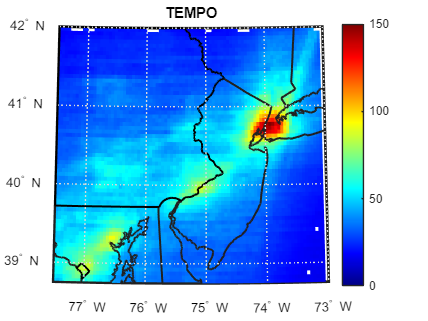

this_year = "2024";
this_month = "8";

lat_bounds = [38.75 42];
lon_bounds = [-77.5 -73];

color_lim =      [0 150];
color_lim_diff = [-20 20];
c = [num2str(this_month),'_',num2str(this_year)];
US_states = readgeotable('cb_2023_us_state_500k.shp');
lw = 1.5;
% font_size = 30;
% resolution = 300;
USA = load("./misc/USA.mat");
USA = USA.USA;


avg_files = dir([save_folder,'/*.mat']);

month_files = avg_files(contains({avg_files.name}, c),:);

tempo_file = month_files(contains({month_files.name}, 'TEMPO'),:);
tropomi_file = month_files(contains({month_files.name}, 'TROPOMI'),:);
merged_file = month_files(contains({month_files.name}, 'MERGED'),:);

tempo_data = load(fullfile(tempo_file.folder,tempo_file.name));
tropomi_data = load(fullfile(tropomi_file.folder,tropomi_file.name));
merged_data = load(fullfile(merged_file.folder,merged_file.name));

figure;
usamap(lat_bounds,lon_bounds)
surfm(tempo_data.lat_grid,tempo_data.lon_grid,tempo_data.no2_interp .* 10^6 ./ conversion_factor('trop-tempo'))
geoshow(US_states, "DisplayType", "polygon", 'FaceAlpha', 0, 'LineWidth', lw);
title('TEMPO')
colorbar;
colormap('jet')
ax = gca;
ax.CLim = color_lim;

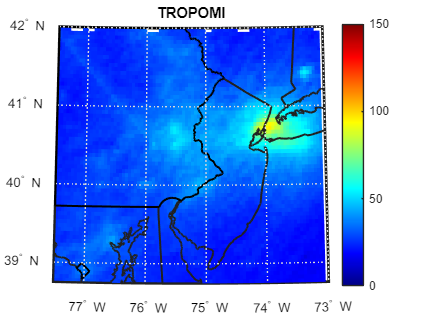


figure;
usamap(lat_bounds,lon_bounds)
surfm(tropomi_data.lat_grid,tropomi_data.lon_grid,tropomi_data.no2_interp .* 10^6)
geoshow(US_states, "DisplayType", "polygon", 'FaceAlpha', 0, 'LineWidth', lw);
title('TROPOMI')
colorbar;
colormap('jet')
ax = gca;
ax.CLim = color_lim;

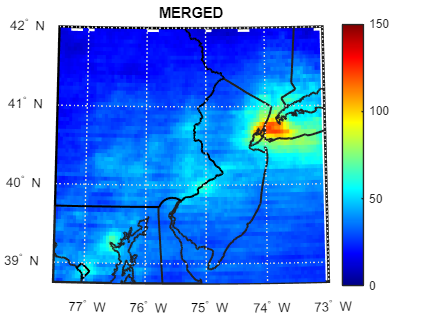


figure;
usamap(lat_bounds,lon_bounds)
surfm(merged_data.lat_grid,merged_data.lon_grid,merged_data.no2_interp .* 10^6)
geoshow(US_states, "DisplayType", "polygon", 'FaceAlpha', 0, 'LineWidth', lw);
title('MERGED')
colorbar;
colormap('jet')
ax = gca;
ax.CLim = color_lim;

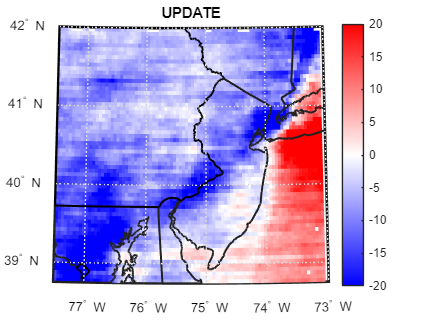


figure;
usamap(lat_bounds,lon_bounds)
surfm(merged_data.lat_grid,merged_data.lon_grid, merged_data.no2_interp .* 10^6 - (tempo_data.no2_interp .* 10^6 ./ conversion_factor('trop-tempo')))
geoshow(US_states, "DisplayType", "polygon", 'FaceAlpha', 0, 'LineWidth', lw);
title('UPDATE')
colorbar;
colormap(USA)
ax = gca;
ax.CLim = color_lim_diff;